                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    2.499720e+03    1.708e+00    1.251e-02
    1      10    2.500944e+03    1.700e+00    2.622e-01    1.599e+00
    2      22    2.500905e+03    1.700e+00    2.394e-03    5.929e-02
    3      27    2.501163e+03    1.698e+00    3.582e-01    3.358e-01
    4      37    2.501115e+03    1.698e+00    1.132e-03    6.870e-02
    5      42    2.501412e+03    1.696e+00    7.638e-04    3.955e-01
    6      47    2.503107e+03    1.685e+00    1.559e-02    2.266e+00
    7      52    2.511471e+03    1.630e+00    1.728e-01    1.125e+01
    8      66    2.511406e+03    1.630e+00    6.016e-03    9.955e-02
    9      71    2.511835e+03    1.627e+00    3.945e-01    5.601e-01
   10      79    2.511803e+03    1.627e+00    1.712e-02    4.921e-01
   11      84    2.513924e+03    1.613e+00    2.105e-01    3.000e+00
   12      94    2.513782e+03    1.614e+00    4

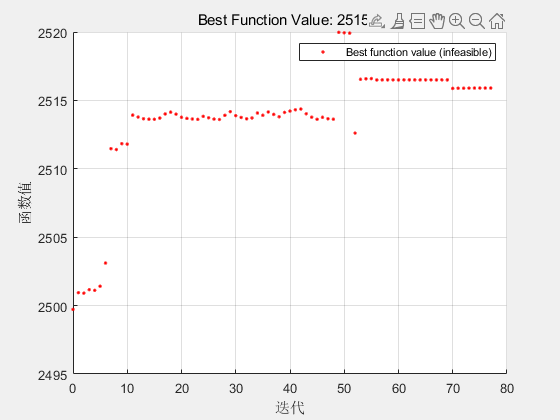


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



clc
clear
close all
addpath("src\");

r = 42164; % km
MU = 398600.4118; % km^3/s^2
p.n = sqrt(MU / r^3);
p.tspan = 0.1;
p.f = 0.0686 / 2 * 1e-3; % N/kg
% p.f = 3; % km/s
s0 = [-38.9328 -100 10 0 0 0]';
sf = zeros(6, 1);
tf = 60 * 60;
lambda_tf = [15000 * [-0.2755 -0.6439 0.0523] 41.662 * 60]';
[s,fval,exitflag,output] = IndirOptTime6(@(t, x) CwTimeOpt(t, x, p), s0, sf, tf, p, lambda_tf);

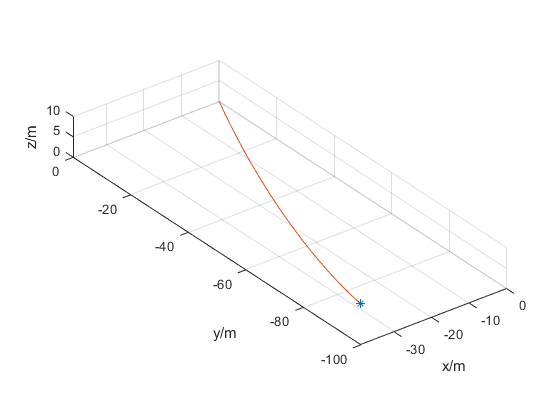

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

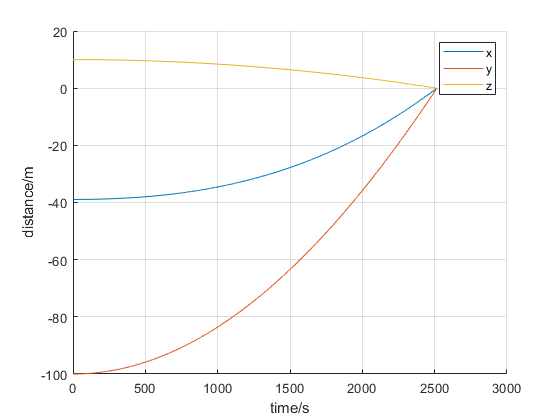

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

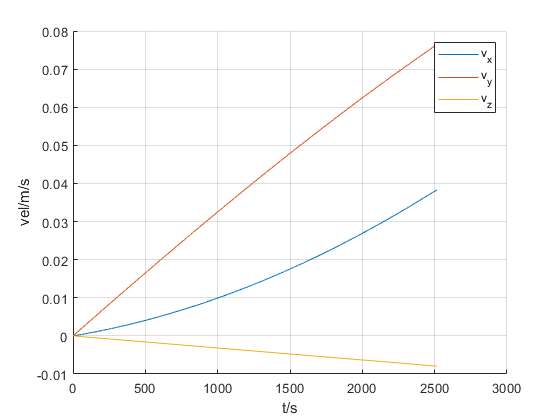

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

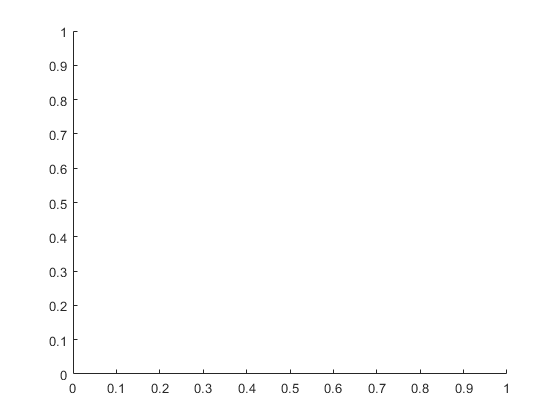

figure
hold on

plot(s(:, 1), s(:, 14 : 17))

Index in position 2 exceeds array bounds. Index must not exceed 13.

grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off